## PART 1: KINEMATICS

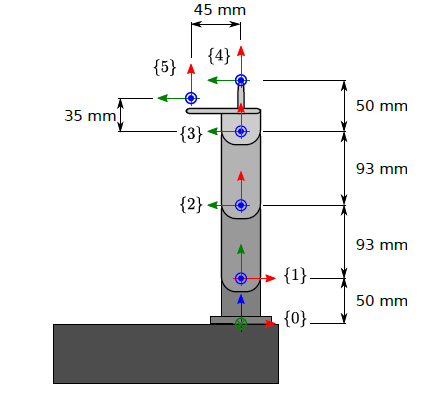

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% Rotation matrices
R_x_90 = [1 0 0;
          0 0 -1;
          0 1 0];
R_z_90 = [0 -1 0;
          1 0 0;
          0 0 1];
R_z_th0 = [cos(theta0) -sin(theta0) 0;
       sin(theta0) cos(theta0) 0;
       0 0 1];
R_z_th1 = [cos(theta1) -sin(theta1) 0;
       sin(theta1) cos(theta1) 0;
       0 0 1];
R_z_th2 = [cos(theta2) -sin(theta2) 0;
       sin(theta2) cos(theta2) 0;
       0 0 1];
R_z_th3 = [cos(theta3) -sin(theta3) 0;
       sin(theta3) cos(theta3) 0;
       0 0 1];

R01 = R_x_90*R_z_th0;
R12 = R_z_90*R_z_th1;
R23 = R_z_th2;
R34 = R_z_th3;
R35 = R_z_th3;

% Translation matrices
t01 = [0 0 L01]';
t12 = [L12 0 0]';
t23 = [L23 0 0]';
t34 = [0 0 L34]';
t35 = [0 0 L35]';

% {0} -> {1}
T01 = [R01 t01;
        zeros(1,3) 1];

% {1} -> {2}
T12 = [R12 t12;
       zeros(1,3) 1];

% {2} -> {3}
T23 = [R23 t23;
       zeros(1,3) 1];

% {3} -> {4}
T34 = [R34 t34;
       zeros(1,3) 1];

% {3} -> {5}
T35 = [R35 t35;
       zeros(1,3) 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1}-\cos\left(\theta_{3}\right)\,\sigma_{3} & 0 & 93\,\cos\left(\theta_{0}\right)-93\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\\ 0 & 0 & -1 & -50\\ \cos\left(\theta_{3}\right)\,\sigma_{3}-\sigma_{1} & \sigma_{2} & 0 & 93\,\sin\left(\theta_{0}\right)+93\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-93\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)\\ \sigma_{2}=-\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)-\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right) \end{array}$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1}-\cos\left(\theta_{3}\right)\,\sigma_{3} & 0 & 93\,\cos\left(\theta_{0}\right)-93\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\\ 0 & 0 & -1 & -35\\ \cos\left(\theta_{3}\right)\,\sigma_{3}-\sigma_{1} & \sigma_{2} & 0 & 93\,\sin\left(\theta_{0}\right)+93\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-93\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)\\ \sigma_{2}=-\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)-\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

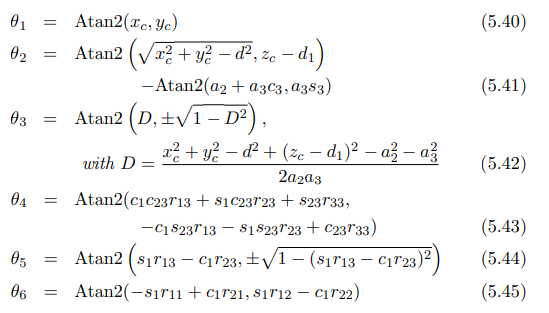

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



theta0 = atan2(xc,yc);

theta2 = atan2(D, sqrt(1-D^2));

theta1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(theta3), L23*sin(theta3));

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





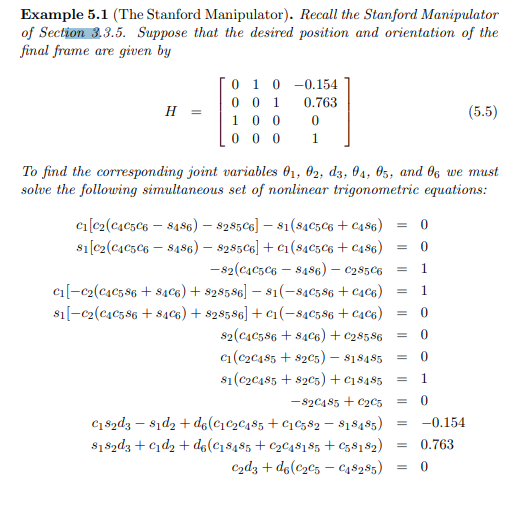

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

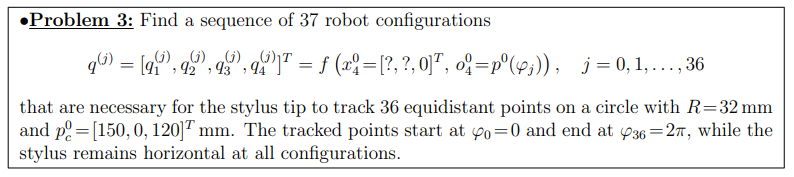


% origin of the circle to be traced
xc = 150;
yc = 100;
zc = 100;

angles = 0:2*pi/36:2*pi % this is the phi angle reported in the previous line

angles =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708    1.7453    1.9199    2.0944    2.2689    2.4435    2.6180    2.7925    2.9671    3.1416    3.3161    3.4907    3.6652    3.8397    4.0143    4.1888    4.3633    4.5379    4.7124    4.8869    5.0615    5.2360    5.4105    5.5851    5.7596    5.9341    6.1087    6.2832




dy = cos(angles)*50;
dz = sin(angles)*50;

x = xc*ones(1,length(angles))

x =    150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150   150


y = yc + dy

y =   150.0000  149.2404  146.9846  143.3013  138.3022  132.1394  125.0000  117.1010  108.6824  100.0000   91.3176   82.8990   75.0000   67.8606   61.6978   56.6987   53.0154   50.7596   50.0000   50.7596   53.0154   56.6987   61.6978   67.8606   75.0000   82.8990   91.3176  100.0000  108.6824  117.1010  125.0000  132.1394  138.3022  143.3013  146.9846  149.2404  150.0000


z = zc + dz

z =   100.0000  108.6824  117.1010  125.0000  132.1394  138.3022  143.3013  146.9846  149.2404  150.0000  149.2404  146.9846  143.3013  138.3022  132.1394  125.0000  117.1010  108.6824  100.0000   91.3176   82.8990   75.0000   67.8606   61.6978   56.6987   53.0154   50.7596   50.0000   50.7596   53.0154   56.6987   61.6978   67.8606   75.0000   82.8990   91.3176  100.0000





% Taras insert magic here. Please transform thew set of
% coordinates[x,y,z](37 points of each) into a set of coordinates

% Stylus always parallel to the ground
x04 = [0, 0, 1];
pos = [x; y; z];

for p = 1:size(pos,2)
    [t1(p),t2(p),t3(p),t4(p)] = invKinematics(x04, pos(:,p));
end

Angles:
 theta1: 
    0.7854

 theta2: 
    0.8279

 theta3: 
   63.5604

 theta4: 
  -62.8176

Angles:
 theta1: 
    0.7829

 theta2: 
   -0.9144

 theta3: 
   60.0129

 theta4: 
  -57.5277

Angles:
 theta1: 
    0.7752

 theta2: 
    0.1828

 theta3: 
   55.8735

 theta4: 
  -54.4855

Angles:
 theta1: 
    0.7626

 theta2: 
    1.0332

 theta3: 
   51.2510

 theta4: 
  -50.7133

Angles:
 theta1: 
    0.7448

 theta2: 
    1.7196

 theta3: 
   46.3092

 theta4: 
  -46.4580

Angles:
 theta1: 
    0.7222

 theta2: 
   -0.7827

 theta3: 
   41.2803

 theta4: 
  -38.9268

Angles:
 theta1: 
    0.6947

 theta2: 
   -0.0280

 theta3: 
   36.4888

 theta4: 
  -34.8900

Angles:
 theta1: 
    0.6628

 theta2: 
    1.0665

 theta3: 
   32.3825

 theta4: 
  -31.8782

Angles:
 theta1: 
    0.6270

 theta2: 
   -0.3551

 theta3: 
   29.5320

 theta4: 
  -27.6061

Angles:
 theta1: 
    0.5880

 theta2: 
   -0.8707

 theta3: 
   28.4985

 theta4: 
  -26.0569

Angles:
 theta1: 
    0.5469

 theta2: 




%t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


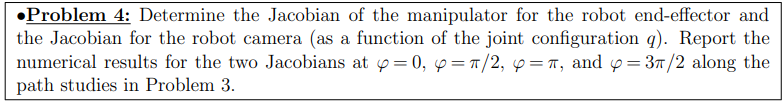

% if you need help figuring out the angles contact Palli
clc
disp("helloo")

helloo


phi = [0 pi/2 pi 3*pi/2];
%phi = pi;
dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

[t1,t2,t3] = theta(x,y,z);
t4 = ones(1,length(x)).*(pi-t1-t2-t3);

for i = 1:1%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34)
end

T04 =     0.7293    0.6842         0  197.2877
   -0.6842    0.7293         0  -97.8421
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.7293    0.6842         0  160.8235
   -0.6842    0.7293         0  -63.6316
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.7293    0.6842         0   93.0000
   -0.6842    0.7293         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 =      1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 =      0     0     1


o1 =      0     0    50


z2 =      0     0     1


o2 =     93     0    50


z3 =      0     0     1


o3 =   160.8235  -63.6316   50.0000


o4 =   197.2877  -97.8421   50.0000


J0 =      0
     0
     1
     0
     0
     0


J1 =    97.8421
  197.2877
         0
         0
         0
    1.0000


J2 =    97.8421
  104.2877
         0
         0
         0
    1.0000


J3 =    34.2105
   36.4642
         0
         0
         0
    1.0000


J =          0   97.8421   97.8421   34.2105
         0  197.2877  104.2877   36.4642
    1.0000         0         0         0
         0         0         0         0
         0         0         0         0
         0    1.0000    1.0000    1.0000


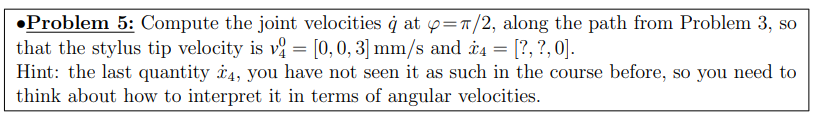

%[T01_old, T12_old, T23_old, T34_old, T35_old] = T_finder(t1(1),t2(1),t3(1),t4(1));

for i = 2:3%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));

    T04=T01*T12*T23*T34
    T03=T01*T12*T23
    T02=T01*T12
    
    o4 = [T04(1,4) T04(2,4) T04(3,4)];

    dt1 = t1(i) - t1(i-1);
    dt2 = t2(i) - t2(i-1);
    dt3 = t3(i) - t3(i-1);
    dt4 = t4(i) - t4(i-1);

    k1 = [T01(1,4); T01(2,4); T01(3,4)];
    k1 = k1*(1/max(k1));
    k2 = [T12(1,4); T12(2,4); T12(3,4)];
    k2 = k2*(1/max(k2));
    k3 = [T23(1,4); T23(2,4); T23(3,4)];
    k3 = k3*(1/max(k3));
    k4 = [T34(1,4); T34(2,4); T34(3,4)];
    k4 = k4*(1/max(k4));

    w01 = dt1*k1;
    w12 = dt2*k2;
    w23 = dt3*k3;
    w34 = dt4*k4;

    R01 = [T01(1,1) T01(1,2) T01(1,3);T01(2,1) T01(2,2) T01(2,3);T01(3,1) T01(3,2) T01(3,3)];
    R02 = [T02(1,1) T02(1,2) T02(1,3);T02(2,1) T02(2,2) T02(2,3);T02(3,1) T02(3,2) T02(3,3)];
    R03 = [T03(1,1) T03(1,2) T03(1,3);T03(2,1) T03(2,2) T03(2,3);T03(3,1) T03(3,2) T03(3,3)];
    R04 = [T04(1,1) T04(1,2) T04(1,3);T04(2,1) T04(2,2) T04(2,3);T04(3,1) T04(3,2) T04(3,3)];

    w04 = w01 + R01*w12 + R02*w23 + R03*w34;

    v04 = cross(w04,o4)
    




end

T04 =     0.5248    0.8512         0  168.0413
   -0.8512    0.5248         0 -121.7284
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.5248    0.8512         0  141.8031
   -0.8512    0.5248         0  -79.1660
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.5248    0.8512         0   93.0000
   -0.8512    0.5248         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


v04 =   -11.2721    6.2930   53.2045


T04 =     0.3055    0.9522         0  136.6872
   -0.9522    0.3055         0 -136.1632
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.3055    0.9522         0  121.4119
   -0.9522    0.3055         0  -88.5537
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.3055    0.9522         0   93.0000
   -0.9522    0.3055         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


v04 =   -11.5201    8.4023   54.3746


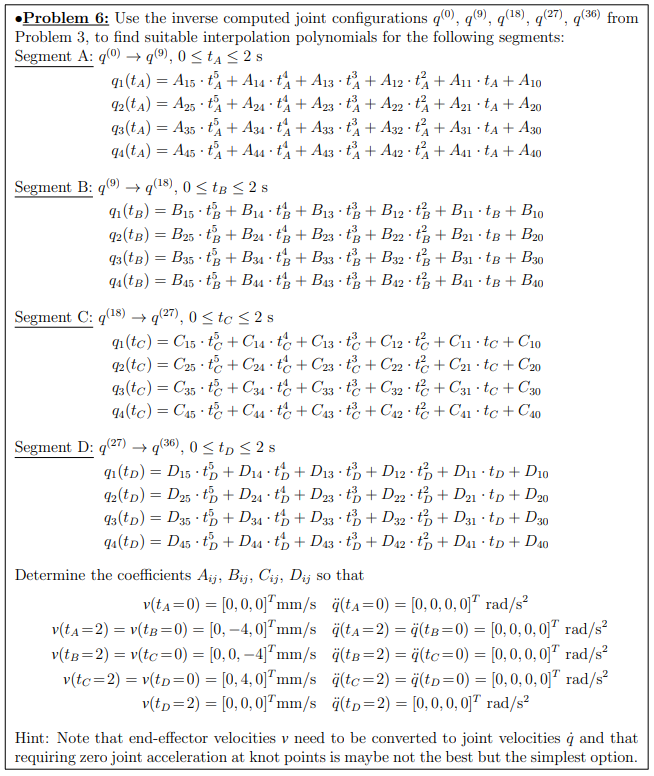

%load("t1.mat");
%load("t2.mat");
%load("t3.mat");
%load("t4.mat");
tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval
MatrixofQ = [t1(1) t1(10) t1(19) t1(28) t1(37);
             t2(1) t2(10) t2(19) t2(28) t2(37);
             t3(1) t3(10) t3(19) t3(28) t3(37);
             t4(1) t4(10) t4(19) t4(28) t4(37)];%t(1), t(10), t(19), t(28), t(37) is

Index exceeds the number of array elements. Index must not exceed 4.

                                                %relative to q(0), q(9), q(18), q(27), q(36)
V0 = [0;0;0;0;0;0];
VA = [0;-4;0;0;0;0];
VB = [0;0;-4;0;0;0];
VC = [0;4;0;0;0;0];
VD = [0;0;0;0;0;0];
%vectors of end-effffector velocities v 
JA = getJacobian(10);
JB = getJacobian(19);
JC = getJacobian(28);
JD = getJacobian(37);
%jaconbian matrix for calculating joint velocities ˙q
v0=0;
I=eye(4);
b=[0; 0; 0; 0];
JAp=inv(JA'*JA)*JA';
JBp=inv(JB'*JB)*JB';
JCp=inv(JC'*JC)*JC';
JDp=inv(JD'*JD)*JD';
vA=JAp*VA+(I-JAp*JA)*b;
vB=JBp*VB+(I-JBp*JB)*b;
vC=JCp*VC+(I-JCp*JC)*b;
vD=JDp*VD+(I-JDp*JD)*b;
%Calculation of joint velocities ˙q
ain = 0;
aout = 0;
%acceleration is always 0

A1 = getConstant(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);
A2 = getConstant(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A3 = getConstant(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A4 = getConstant(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A = [A1;A2;A3;A4];

B1 = getConstant(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B2 = getConstant(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B3 = getConstant(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B4 = getConstant(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B = [B1;B2;B3;B4];

C1 = getConstant(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);
C2 = getConstant(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C3 = getConstant(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C4 = getConstant(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C = [C1;C2;C3;C4];

D1 = getConstant(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);
D2 = getConstant(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D3 = getConstant(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D4 = getConstant(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D = [D1;D2;D3;D4];
%Calculation of Coefficients in Interpolation Functions

x = 0:0.01:8;
q1A = A1(6) * x.^5 + A1(5) * x.^4 + A1(4) * x.^3 + A1(3) * x.^2 + A1(2) * x + A1(1);
q2A = A2(6) * x.^5 + A2(5) * x.^4 + A2(4) * x.^3 + A2(3) * x.^2 + A2(2) * x + A2(1);
q3A = A3(6) * x.^5 + A3(5) * x.^4 + A3(4) * x.^3 + A3(3) * x.^2 + A3(2) * x + A3(1);
q4A = A4(6) * x.^5 + A4(5) * x.^4 + A4(4) * x.^3 + A4(3) * x.^2 + A4(2) * x + A4(1);

q1B = B1(6) * x.^5 + B1(5) * x.^4 + B1(4) * x.^3 + B1(3) * x.^2 + B1(2) * x + B1(1);
q2B = B2(6) * x.^5 + B2(5) * x.^4 + B2(4) * x.^3 + B2(3) * x.^2 + B2(2) * x + B2(1);
q3B = B3(6) * x.^5 + B3(5) * x.^4 + B3(4) * x.^3 + B3(3) * x.^2 + B3(2) * x + B3(1);
q4B = B4(6) * x.^5 + B4(5) * x.^4 + B4(4) * x.^3 + B4(3) * x.^2 + B4(2) * x + B4(1);

q1C = C1(6) * x.^5 + C1(5) * x.^4 + C1(4) * x.^3 + C1(3) * x.^2 + C1(2) * x + C1(1);
q2C = C2(6) * x.^5 + C2(5) * x.^4 + C2(4) * x.^3 + C2(3) * x.^2 + C2(2) * x + C2(1);
q3C = C3(6) * x.^5 + C3(5) * x.^4 + C3(4) * x.^3 + C3(3) * x.^2 + C3(2) * x + C3(1);
q4C = C4(6) * x.^5 + C4(5) * x.^4 + C4(4) * x.^3 + C4(3) * x.^2 + C4(2) * x + C4(1);

q1D = D1(6) * x.^5 + D1(5) * x.^4 + D1(4) * x.^3 + D1(3) * x.^2 + D1(2) * x + D1(1);
q2D = D2(6) * x.^5 + D2(5) * x.^4 + D2(4) * x.^3 + D2(3) * x.^2 + D2(2) * x + D2(1);
q3D = D3(6) * x.^5 + D3(5) * x.^4 + D3(4) * x.^3 + D3(3) * x.^2 + D3(2) * x + D3(1);
q4D = D4(6) * x.^5 + D4(5) * x.^4 + D4(4) * x.^3 + D4(3) * x.^2 + D4(2) * x + D4(1);
figure; % Create a new figure window
y1 = q1A.*(x>=0&x<=2) + q1B.*(x>2&x<=4) + q1C.*(x>4&x<=6) + q1D.*(x>6&x<=8);
plot(y1, 'b');
hold on
y2 = q2A.*(x>=0&x<=2) + q2B.*(x>2&x<=4) + q2C.*(x>4&x<=6) + q2D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q3A.*(x>=0&x<=2) + q3B.*(x>2&x<=4) + q3C.*(x>4&x<=6) + q3D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q4A.*(x>=0&x<=2) + q4B.*(x>2&x<=4) + q4C.*(x>4&x<=6) + q4D.*(x>6&x<=8);
plot(x, y1, 'y'); 

%%seven knot points
A71 = getConstant7(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1),ain,aout);
A72 = getConstant7(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1),ain,aout);
A73 = getConstant7(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1),ain,aout);
A74 = getConstant7(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1),ain,aout);
A7 = [A71 A72 A73 A74];
 
B71 = getConstant7(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1),ain,aout);
B72 = getConstant7(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1),ain,aout);
B73 = getConstant7(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1),ain,aout);
B74 = getConstant7(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1),ain,aout);
B7 = [B71 B72 B73 B74];

C71 = getConstant7(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1),ain,aout);
C72 = getConstant7(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1),ain,aout);
C73 = getConstant7(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1),ain,aout);
C74 = getConstant7(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1),ain,aout);
C7 = [C71 C72 C73 C74];

D71 = getConstant7(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1),ain,aout);
D72 = getConstant7(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1),ain,aout);
D73 = getConstant7(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1),ain,aout);
D74 = getConstant7(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1),ain,aout);
D7 = [D71 D72 D73 D74];

x = 0:0.01:8;
q71A = A71(8) * x.^7 + A71(7) * x.^6 + A71(6) * x.^5 + A71(5) * x.^4 + A71(4) * x.^3 + A71(3) * x.^2 + A71(2) * x + A71(1);
q72A = A72(8) * x.^7 + A72(7) * x.^6 + A72(6) * x.^5 + A72(5) * x.^4 + A72(4) * x.^3 + A72(3) * x.^2 + A72(2) * x + A72(1);
q73A = A73(8) * x.^7 + A73(7) * x.^6 + A73(6) * x.^5 + A73(5) * x.^4 + A73(4) * x.^3 + A73(3) * x.^2 + A73(2) * x + A73(1);
q74A = A74(8) * x.^7 + A74(7) * x.^6 + A74(6) * x.^5 + A74(5) * x.^4 + A74(4) * x.^3 + A74(3) * x.^2 + A74(2) * x + A74(1);

q71B = B71(8) * x.^7 + B71(7) * x.^6 + B71(6) * x.^5 + B71(5) * x.^4 + B71(4) * x.^3 + B71(3) * x.^2 + B71(2) * x + B71(1);
q72B = B72(8) * x.^7 + B72(7) * x.^6 + B72(6) * x.^5 + B72(5) * x.^4 + B72(4) * x.^3 + B72(3) * x.^2 + B72(2) * x + B72(1);
q73B = B73(8) * x.^7 + B73(7) * x.^6 + B73(6) * x.^5 + B73(5) * x.^4 + B73(4) * x.^3 + B73(3) * x.^2 + B73(2) * x + B73(1);
q74B = B74(8) * x.^7 + B74(7) * x.^6 + B74(6) * x.^5 + B74(5) * x.^4 + B74(4) * x.^3 + B74(3) * x.^2 + B74(2) * x + B74(1);

q71C = C71(8) * x.^7 + C71(7) * x.^6 + C71(6) * x.^5 + C71(5) * x.^4 + C71(4) * x.^3 + C71(3) * x.^2 + C71(2) * x + C71(1);
q72C = C72(8) * x.^7 + C72(7) * x.^6 + C72(6) * x.^5 + C72(5) * x.^4 + C72(4) * x.^3 + C72(3) * x.^2 + C72(2) * x + C72(1);
q73C = C73(8) * x.^7 + C73(7) * x.^6 + C73(6) * x.^5 + C73(5) * x.^4 + C73(4) * x.^3 + C73(3) * x.^2 + C73(2) * x + C73(1);
q74C = C74(8) * x.^7 + C74(7) * x.^6 + C74(6) * x.^5 + C74(5) * x.^4 + C74(4) * x.^3 + C74(3) * x.^2 + C74(2) * x + C74(1);

q71D = D71(8) * x.^7 + D71(7) * x.^6 + D71(6) * x.^5 + D71(5) * x.^4 + D71(4) * x.^3 + D71(3) * x.^2 + D71(2) * x + D71(1);
q72D = D72(8) * x.^7 + D72(7) * x.^6 + D72(6) * x.^5 + D72(5) * x.^4 + D72(4) * x.^3 + D72(3) * x.^2 + D72(2) * x + D72(1);
q73D = D73(8) * x.^7 + D73(7) * x.^6 + D73(6) * x.^5 + D73(5) * x.^4 + D73(4) * x.^3 + D73(3) * x.^2 + D73(2) * x + D73(1);
q74D = D74(8) * x.^7 + D74(7) * x.^6 + D74(6) * x.^5 + D74(5) * x.^4 + D74(4) * x.^3 + D74(3) * x.^2 + D74(2) * x + D74(1);
figure; % Create a new figure window
y1 = q71A.*(x>=0&x<=2) + q71B.*(x>2&x<=4) + q71C.*(x>4&x<=6) + q71D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q72A.*(x>=0&x<=2) + q72B.*(x>2&x<=4) + q72C.*(x>4&x<=6) + q72D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q73A.*(x>=0&x<=2) + q73B.*(x>2&x<=4) + q73C.*(x>4&x<=6) + q73D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q74A.*(x>=0&x<=2) + q74B.*(x>2&x<=4) + q74C.*(x>4&x<=6) + q74D.*(x>6&x<=8);
plot(x, y1, 'y'); 

%%three knot points
A31 = getConstant3(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA(1,1));
A32 = getConstant3(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA(1,1));
A33 = getConstant3(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA(1,1));
A34 = getConstant3(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA(1,1));
A3 = [A31 A32 A33 A34];
 
B31 = getConstant3(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA(1,1),vB(2,1));
B32 = getConstant3(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA(1,1),vB(2,1));
B33 = getConstant3(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA(1,1),vB(2,1));
B34 = getConstant3(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA(1,1),vB(2,1));
B3 = [B31 B32 B33 B34];

C31 = getConstant3(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB(2,1),vC(3,1));
C32 = getConstant3(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB(2,1),vC(3,1));
C33 = getConstant3(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB(2,1),vC(3,1));
C34 = getConstant3(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB(2,1),vC(3,1));
C3 = [C31 C32 C33 C34];

D31 = getConstant3(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC(3,1),vD(4,1));
D32 = getConstant3(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC(3,1),vD(4,1));
D33 = getConstant3(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC(3,1),vD(4,1));
D34 = getConstant3(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC(3,1),vD(4,1));
D3 = [D31 D32 D33 D34];

x = 0:0.01:8;
q31A = A31(4) * x.^3 + A31(3) * x.^2 + A31(2) * x + A31(1);
q32A = A32(4) * x.^3 + A32(3) * x.^2 + A32(2) * x + A32(1);
q33A = A33(4) * x.^3 + A33(3) * x.^2 + A33(2) * x + A33(1);
q34A = A34(4) * x.^3 + A34(3) * x.^2 + A34(2) * x + A34(1);

q31B = B31(4) * x.^3 + B31(3) * x.^2 + B31(2) * x + B31(1);
q32B = B32(4) * x.^3 + B32(3) * x.^2 + B32(2) * x + B32(1);
q33B = B33(4) * x.^3 + B33(3) * x.^2 + B33(2) * x + B33(1);
q34B = B34(4) * x.^3 + B34(3) * x.^2 + B34(2) * x + B34(1);

q31C = C31(4) * x.^3 + C31(3) * x.^2 + C31(2) * x + C31(1);
q32C = C32(4) * x.^3 + C32(3) * x.^2 + C32(2) * x + C32(1);
q33C = C33(4) * x.^3 + C33(3) * x.^2 + C33(2) * x + C33(1);
q34C = C34(4) * x.^3 + C34(3) * x.^2 + C34(2) * x + C34(1);

q31D = D31(4) * x.^3 + D31(3) * x.^2 + D31(2) * x + D31(1);
q32D = D32(4) * x.^3 + D32(3) * x.^2 + D32(2) * x + D32(1);
q33D = D33(4) * x.^3 + D33(3) * x.^2 + D33(2) * x + D33(1);
q34D = D34(4) * x.^3 + D34(3) * x.^2 + D34(2) * x + D34(1);
figure; % Create a new figure window
y1 = q31A.*(x>=0&x<=2) + q31B.*(x>2&x<=4) + q31C.*(x>4&x<=6) + q31D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q32A.*(x>=0&x<=2) + q32B.*(x>2&x<=4) + q32C.*(x>4&x<=6) + q32D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q33A.*(x>=0&x<=2) + q33B.*(x>2&x<=4) + q33C.*(x>4&x<=6) + q33D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q34A.*(x>=0&x<=2) + q34B.*(x>2&x<=4) + q34C.*(x>4&x<=6) + q34D.*(x>6&x<=8);
plot(x, y1, 'y'); 

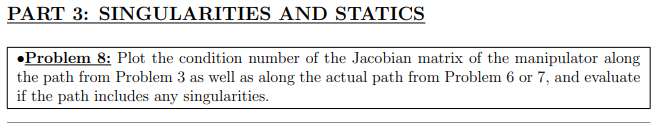


k=zeros(1,length(t1))
for i = 1:length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34); % Get jacobian at a given point
    J = [J(1:3,:);J(6,:)] ;% Remove rows that we do not wish to control
    k(i) = norm(inv(J))*norm(J); % calculate the condition number
end
figure;
plot(k,'.-')
xlabel('Joint configuration')
ylabel('Condition number')
disp('Can be seen that the configuration is far from reaching singularity since the')
disp('condition number only reaches around 430 which is far from infinity')

% this uses the collection of angles from problem 3
len = length(t1);
torque2 = zeros(1,len);
torque3 = zeros(1,len);
torque4 = zeros(1,len);

for i=1:len
    [torque2(i),torque3(i),torque4(i)] = torques(t2(i),t3(i),t4(i),1);
end

figure
plot(t2,torque2)
hold on

plot(t3,torque3)

%plot(t4,torque4)

legend(["motor1", "motor2"])%,"motor3"])

disp("Motor 4 is omitted here as the torques are smaller than")